f = @(x) x + sin(x.^2)

f = function_handle with value:
    @(x)x+sin(x.^2)


fd = @(x) 1 + 2.*x .* cos(x.^2);
fdd = @(x) 2 .* cos(x.^2) - 4 .* x.^2 .* sin(x.^2);

a = -pi;
b = pi;
n = 10;

t = linspace(a, b, 200);
f_t = f(t);
yd = fd([a, b]);
ydd = fdd([a, b]);

## Spline

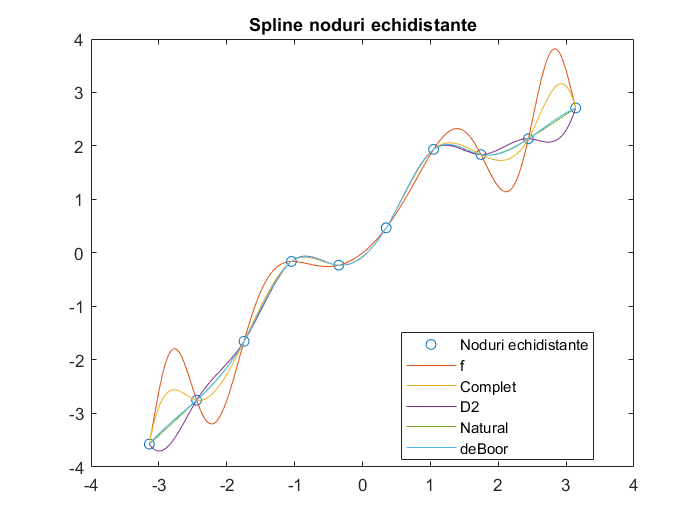

% Spline, noduri echidistante
x = linspace(a, b, n);
y = f(x);

cc1 = CubicSplinec(x, y, 0, yd);
cc2 = CubicSplinec(x, y, 1, ydd);
cc3 = CubicSplinec(x, y, 2);
cc4 = CubicSplinec(x, y, 3);

z1 = evalsplinec(x, cc1, t);
z2 = evalsplinec(x, cc2, t);
z3 = evalsplinec(x, cc3, t);
z4 = evalsplinec(x, cc4, t);

plot(x, y, 'o', t, f_t, t, z1, t, z2, t, z3, t, z4);
title('Spline noduri echidistante');
legend('Noduri echidistante', 'f', 'Complet', 'D2', 'Natural', 'deBoor', 'Location', 'best');

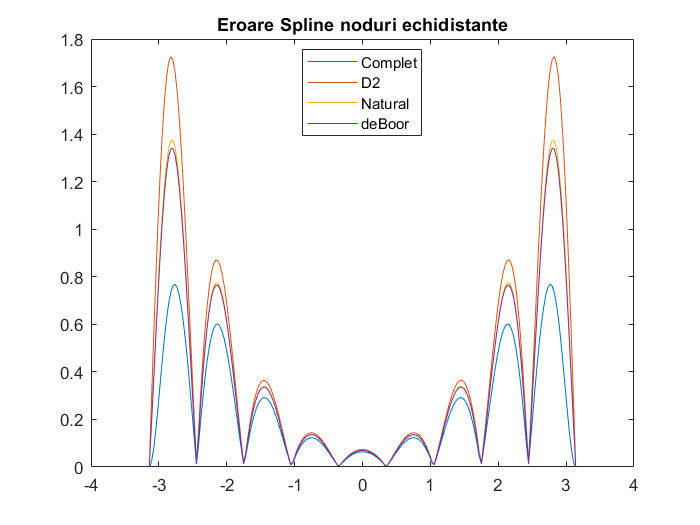

plot(t', abs(repmat(f_t', 1, 4) - [z1, z2, z3, z4]))
title('Eroare Spline noduri echidistante');
legend('Complet', 'D2', 'Natural', 'deBoor', 'Location', 'best');

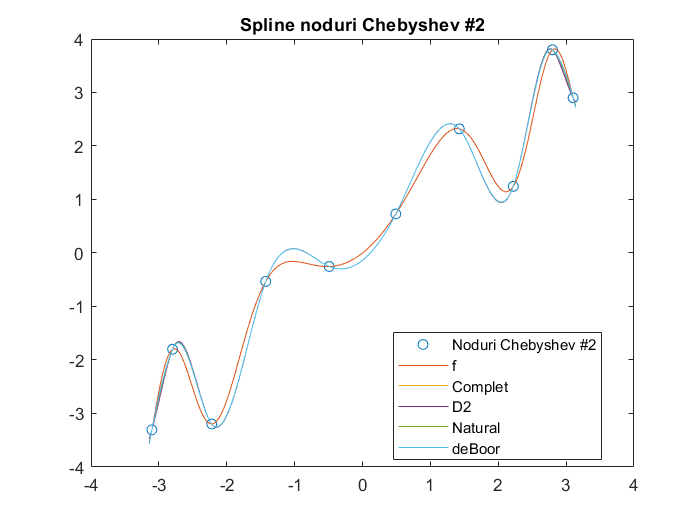

% Spline, noduri Chebyshev de speta a doua
k = 0:n-1;
x = a + (b - a)/2 * (1 - cos((2*k+1)*pi/(2*n)));
y = f(x);

cc1 = CubicSplinec(x, y, 0, yd);
cc2 = CubicSplinec(x, y, 1, ydd);
cc3 = CubicSplinec(x, y, 2);
cc4 = CubicSplinec(x, y, 3);

z1 = evalsplinec(x, cc1, t);
z2 = evalsplinec(x, cc2, t);
z3 = evalsplinec(x, cc3, t);
z4 = evalsplinec(x, cc4, t);

plot(x, y, 'o', t, f_t, t, z1, t, z2, t, z3, t, z4);
title('Spline noduri Chebyshev #2');
legend('Noduri Chebyshev #2', 'f', 'Complet', 'D2', 'Natural', 'deBoor', 'Location', 'best');

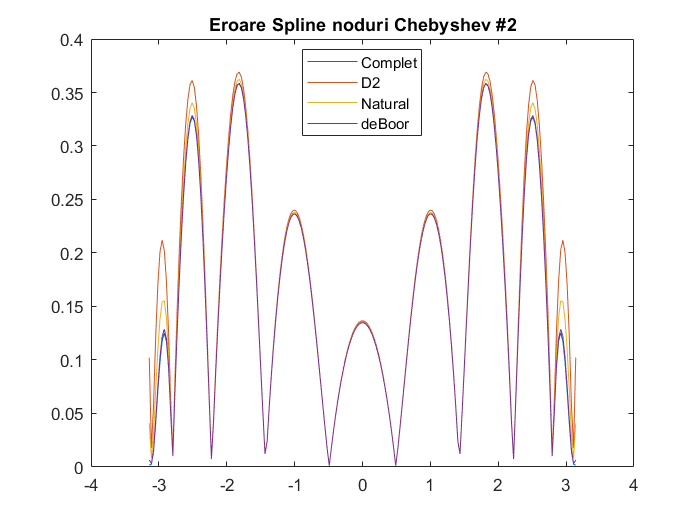

plot(t', abs(repmat(f_t', 1, 4) - [z1, z2, z3, z4]))
title('Eroare Spline noduri Chebyshev #2');
legend('Complet', 'D2', 'Natural', 'deBoor', 'Location', 'best');

## Mcmmp

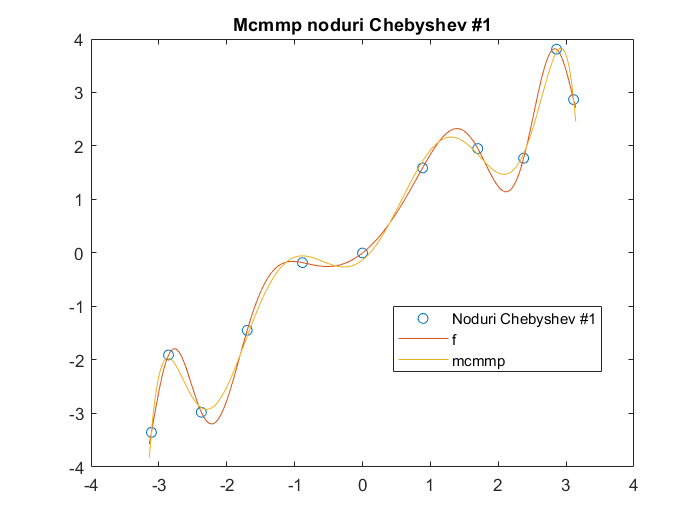

% Noduri Chebyshev de speta intai
k = 0:n;
x = sort(cos(((2 * k + 1) * pi) / (2 * n + 2)) .* pi);
y = f(x);

phi = @(x)[ones(1, length(x)); x; x.^2; x.^3; x.^4; x.^5; x.^6; x.^7; x.^8;];

y_approx = least_squares_approx(x, y, phi, t);

plot(x, y, 'o', t, f_t, t, y_approx);
title('Mcmmp noduri Chebyshev #1');
legend('Noduri Chebyshev #1', 'f', 'mcmmp', 'Location', 'best');

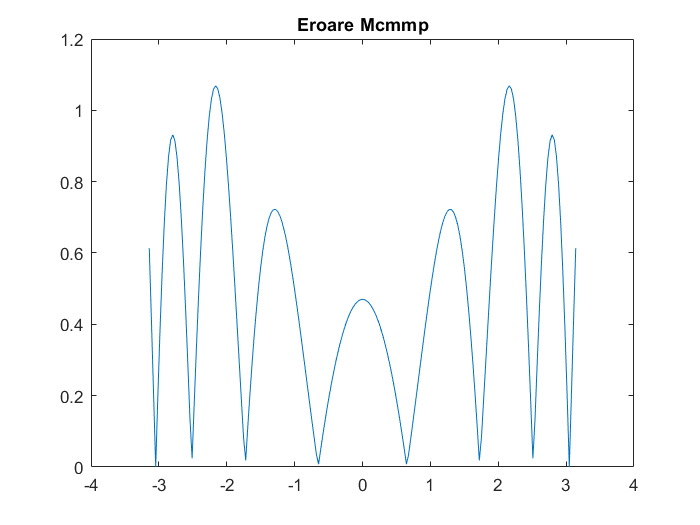

plot(t, abs(f_t - y_approx));
title('Eroare Mcmmp');